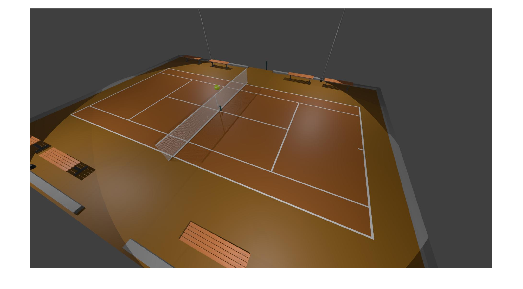

imagePath = "captures\leftImg_1.jpeg";
% Read the image from the specified path
img = imread(imagePath);
imshow(img);

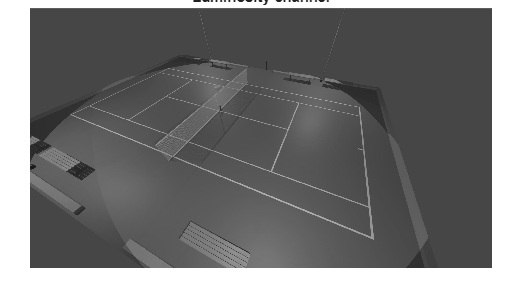


hsvImg = rgb2hsv(img);
H = hsvImg(:, :, 1);
S = hsvImg(:, :, 2);
V = hsvImg(:, :, 3);

yCbCr_Img = rgb2ycbcr(img);
y = yCbCr_Img(:, :, 1); imshow(y); title('Luminosity channel')

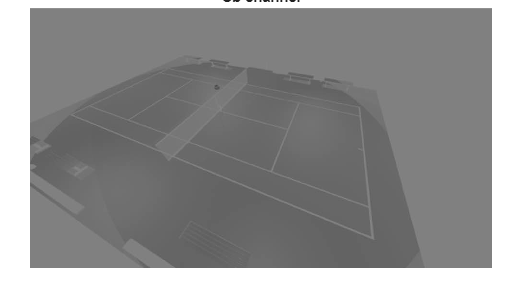

cb = yCbCr_Img(:, :, 2); imshow(cb); title('Cb channel')

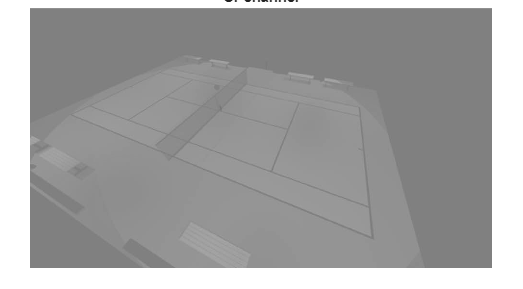

cr = yCbCr_Img(:, :, 3); imshow(cr); title('Cr channel')

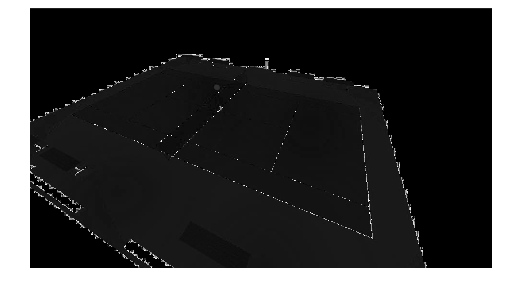


imshow(H)

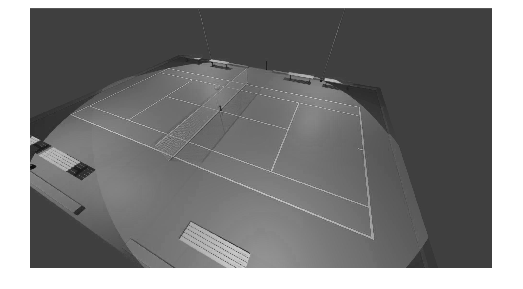

imshow(V)

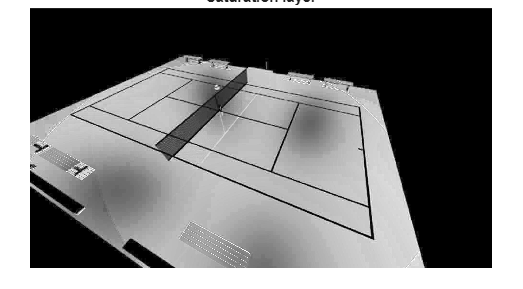

imshow(S); title('Saturation layer')

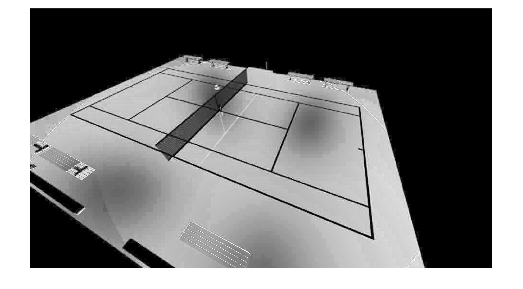


hsvImg(:, :, 2) = S * 1.75; % Increase saturation by 50%
imshow(S)

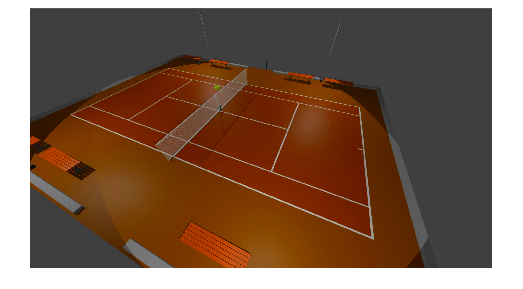


satImg = hsv2rgb(hsvImg);
imshow(satImg)

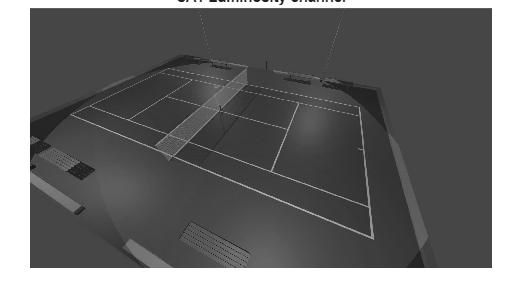


yCbCr_Img = rgb2ycbcr(satImg);
y = yCbCr_Img(:, :, 1); imshow(y); title('SAT Luminosity channel')

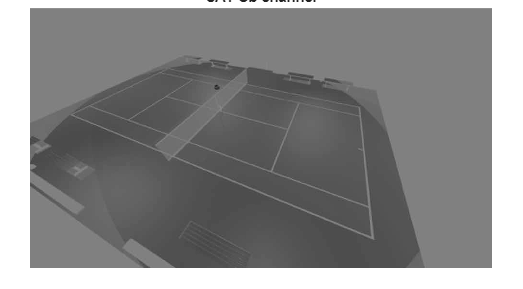

cb = yCbCr_Img(:, :, 2); imshow(cb); title('SAT Cb channel')

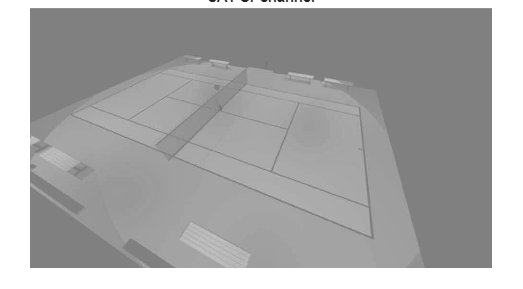

cr = yCbCr_Img(:, :, 3); imshow(cr); title('SAT Cr channel')

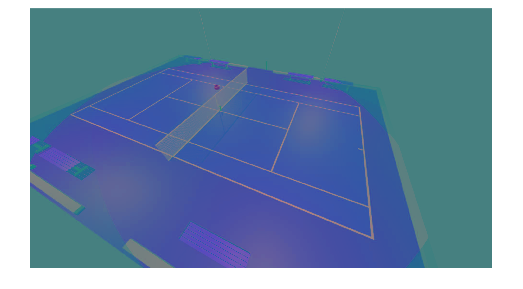


imshow(yCbCr_Img)

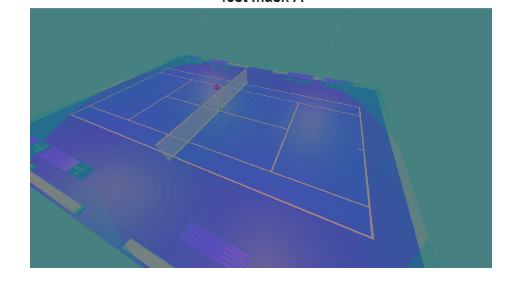

mask = cr > (255 * 0.9);
colorMaskImg = yCbCr_Img;
colorMaskImg(~mask);
imshow(colorMaskImg); title('Test mask A');

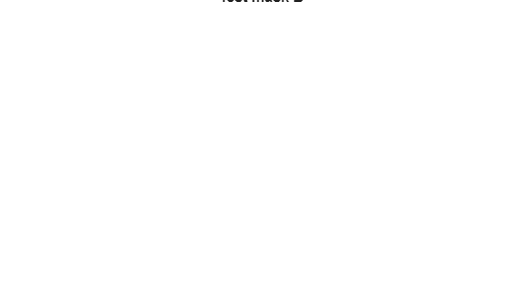


mask = cb < (255 * 0.25);
colorMaskImg = yCbCr_Img;
colorMaskImg(~mask);
imshow(mask); title('Test mask B');

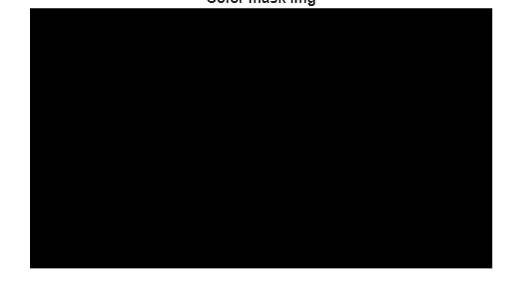


mask = (cb < (255 * 0.25)) & (cr > (255 * 0.5));
colorMaskImg = yCbCr_Img;
colorMaskImg(~mask);
imshow(mask); title('Color mask img');